# Automate Importing Data by Generating Code Using the Database Explorer App

This code reproduces the data obtained using the Database Explorer app by connecting to a database, executing a SQL query, and importing data into the MATLAB® workspace. To use this code, add the password for connecting to the database in the database command.

% Auto-generated by MATLAB (R2023b) and Database Toolbox Version 23.2 on 21-Mar-2024 17:07:38

## Make connection to database

conn = database('MS SQL Server','','');

## Total Distribution of Ratings

%Set query to execute on the database
query = ['SELECT * ' ...
    'FROM LegalReviewsDB.dbo.review_table'];

### Execute query and fetch results

data = fetch(conn,query);

### Storing column data in variables

% fetching data into variables for each column
reviewDates = data.Review_Date;
reviewerNames = data.Reviewer_Name;
ratings = data.Rating;
reviewTexts = data.Review_Text;

### Bar Chart of Distribution of Ratings

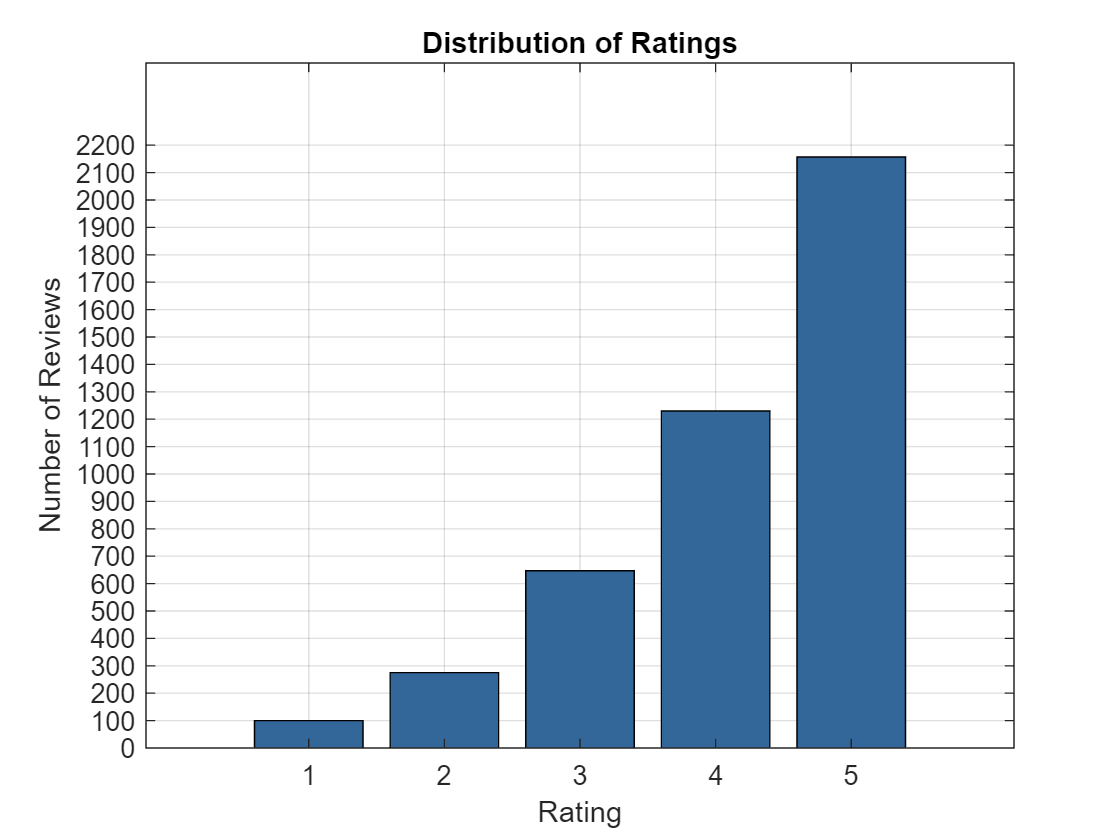


% Calculate the total number of reviews for each rating
ratingCounts = countcats(categorical(ratings));
maxReviews = max(ratingCounts);
numYTicks = ceil(maxReviews/100);
yTickPositions = 0:100:numYTicks*100;

% Plotting the bar chart
bar(1:5, ratingCounts, 'FaceColor', [0.2, 0.4, 0.6]); % Assuming ratings are from 1 to 5
xlabel('Rating');
ylabel('Number of Reviews');
title('Distribution of Ratings');
xticks(1:5); % Assuming ratings are from 1 to 5
yticks(yTickPositions);
grid on;

## Rating averages over time

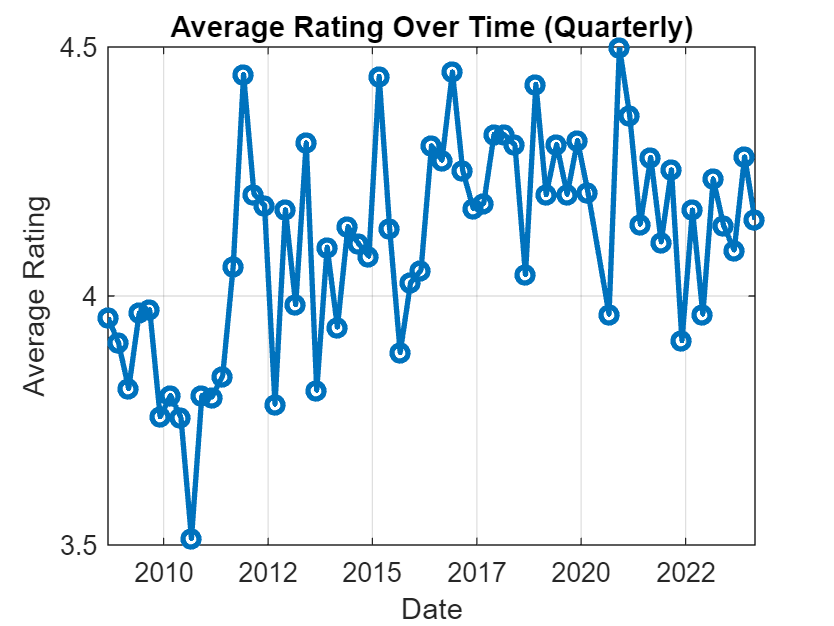

query = ['SELECT YEAR(Review_Date) AS Review_Year, ', ...
         'DATEPART(QUARTER, Review_Date) AS Review_Quarter, ', ...
         'AVG(Rating) AS Average_Rating ', ...
         'FROM LegalReviewsDB.dbo.review_table ', ...
         'GROUP BY YEAR(Review_Date), DATEPART(QUARTER, Review_Date) ', ...
         'ORDER BY Review_Year, Review_Quarter'];

data = fetch(conn, query);

% Extract relevant columns from the fetched data
reviewYear = data.Review_Year;
reviewQuarter = data.Review_Quarter;
averageRating = data.Average_Rating;

% Combine year and quarter into a single date for plotting
dateLabels = datetime(reviewYear, reviewQuarter*3, 1);

% Aggregate data into quarterly intervals
quarterlyAverageRating = zeros(size(dateLabels));
for i = 1:length(dateLabels)
    quarterStart = dateLabels(i);
    quarterEnd = quarterStart + calquarters(1);
    ratingsInQuarter = averageRating(reviewYear == year(quarterStart) & reviewQuarter == quarter(quarterStart));
    quarterlyAverageRating(i) = mean(ratingsInQuarter);
end

% Plotting the quarterly average rating over time
plot(dateLabels, quarterlyAverageRating, '-o', 'LineWidth', 2);
xlabel('Date');
ylabel('Average Rating');
title('Average Rating Over Time (Quarterly)');
datetick('x', 'yyyy', 'keeplimits'); % Format x-axis to display year and specify tick interval
grid on;

## Close connection to database

close(conn)

## Clear variables

clear conn query